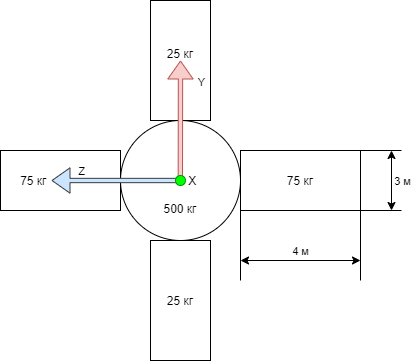

global J
global mdl
global omega0
global SN0

mdl="sputnik";

SN0=[1;0;0;0];
omega0=deg2rad([10; 15; -20]);

% Центр
m_c=500;
r_c=1;

% Размеры панелей
a=4;
b=3;

% Расстояние от центра панелей до центра масс в плоскости YOZ
d=r_c+a/2;

% Панели вертикальные
m_v=25;

% Панели горизонтальные
m_h=100-m_v;

% Моменты инерции центра
Jc_x=(2/5)*m_c*r_c^2;
Jc_y=Jc_x;
Jc_z=Jc_x;

% Собственные моменты инерции вертикальных панелей 
Jv_x=m_v*(a^2+b^2)/12;
Jv_y=m_v*(b^2)/12;
Jv_z=m_v*(a^2)/12;

% Собственные моменты инерции горизонтальных панелей 
Jh_x=m_h*(b^2+a^2)/12;
Jh_y=m_h*(a^2)/12;
Jh_z=m_h*(b^2)/12;

% Суммарные моменты инерции по каждой оси
Jx=Jc_x + (2*Jv_x+2*m_v*d^2) +(2*Jh_x+2*m_h*d^2);
Jy=Jc_y + (2*Jv_y+2*m_v*d^2) +(2*Jh_y+2*m_h*d^2);
Jz=Jc_z + (2*Jv_z+2*m_v*d^2) +(2*Jh_z+2*m_h*d^2);

J=diag([Jx;Jy;Jz]);
sym(J)

$$ans = \left(\begin{array}{ccc} 2.4167e+03 & 0 & 0\\ 0 & 2.2375e+03 & 0\\ 0 & 0 & 2.1792e+03 \end{array}\right)$$


save('params',"J","Jx","Jy","Jz")

% w=[10 40 -30]'
% h=20
% e=abs(w)>h
% w(e) = sign(w(e))*h


% syms q [8,1] real
% 
% v= [q5 q6 q7 q8]'
% a=q1
% b=q2
% c=q3
% d=q4
% 
% A=[
%     a b c d
%     b -a -d c
%     c d -a -b
%     d -c b -a
%     ]
% A*v

% syms x y z R real
% syms c [3,1] real
% syms x1 x2 y1 y2 z1 z2 t real
% 
% x=(1-t)*x1+t*x2
% y=(1-t)*y1+t*y2
% z=(1-t)*z1+t*z2
% 
% eq=(x-c1)^2 +(y-c2)^2 +(z-c3)^2
% ts=solve(eq==R^2,t,"ReturnConditions",true);
% ts=matlabFunction(transpose(ts.t))

% syms J1 J2 J3 real
% syms omega [3,1] real
% syms dw [3,1] real
% syms M [3,1] real
% I=diag([J1 J2 J3])
% w=omega
% 
% % dw = M/J - w x (J*w)
% 
% dw==inv(I)*(M-cross(w,(I*w)))
% 


% syms q [4,1] real
% syms omega [3,1] real
% 
% w=omega

$$w = \left(\begin{array}{c} \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$

% 
% W=[
%     0    -w(1) -w(2) -w(3)
%     w(1)  0     w(3) -w(2)
%     w(2) -w(3)  0     w(1)
%     w(3)  w(2) -w(1)  0
%     ];
% 
% O=[
%     0 -w(1) -w(2) -w(3)
%     0  0     w(3) -w(2)
%     0  0     0     w(1)
%     0  0     0     0
%     ];
% O=O-O'

$$O = \left(\begin{array}{cccc} 0 & -\omega_{1} & -\omega_{2} & -\omega_{3}\\ \omega_{1} & 0 & \omega_{3} & -\omega_{2}\\ \omega_{2} & -\omega_{3} & 0 & \omega_{1}\\ \omega_{3} & \omega_{2} & -\omega_{1} & 0 \end{array}\right)$$

% q

$$q = \left(\begin{array}{c} q_{1}\\ q_{2}\\ q_{3}\\ q_{4} \end{array}\right)$$

% d1=0.5*W*q

$$d1 = \left(\begin{array}{c} -0.5000\,\omega_{1}\,q_{2}-0.5000\,\omega_{2}\,q_{3}-0.5000\,\omega_{3}\,q_{4}\\ 0.5000\,\omega_{1}\,q_{1}-0.5000\,\omega_{2}\,q_{4}+0.5000\,\omega_{3}\,q_{3}\\ 0.5000\,\omega_{1}\,q_{4}+0.5000\,\omega_{2}\,q_{1}-0.5000\,\omega_{3}\,q_{2}\\ -0.5000\,\omega_{1}\,q_{3}+0.5000\,\omega_{2}\,q_{2}+0.5000\,\omega_{3}\,q_{1} \end{array}\right)$$